# Extended Kalman Filter のサンプルコード

p161, カルマンフィルタの基礎, 足立秀一


$$x(k+1) = x(k) + 3\cos{\frac{x(k)}{10}} + v(k), x(0) = 10\\
y(k) = x^3(k) + \omega(k)$$


v(k): 平均値0, 分散1

w(k): 平均値0, 分散100

とりあえず写経

### 問題設定

システム

f = @(x) x + 3*cos(x/10); % 無名関数
h = @(x) x^3;
a = @(x) 1 - 3/10*sin(x/10); % f のヤコビアン
b = 1;
c = @(x) 3*x^2; % h のヤコビアン

データ数・雑音の設定

N = 50;
Q = 1;
R = 100;

### 非線形時系列の生成

雑音信号の生成

v = randn(N, 1)*sqrtm(Q); % システム雑音
w = randn(N, 1)*sqrtm(R); % 観測雑音

記憶領域の確保

x = zeros(N, 1);
y = zeros(N, 1);

初期値

x(1) = 10;
y(1) = h(x(1));

時間更新 (ノイズ込みの状態と観測値)

for k = 2:N
    x(k) = f(x(k-1)) + b*v(k-1);
    y(k) = h(x(k)) + w(k);
end

### EKFアルゴリズムによる推定

記憶領域の確保

xhat = zeros(N, 1);

初期推定値

P = 1;
xhat(1) = x(1) + 1;

推定値の更新

for k = 2:N
    [xhat(k, :), P, G] = ekf(f, h, a, b, c, Q, R, y(k), xhat(k-1, :), P);
end

### 結果の図示

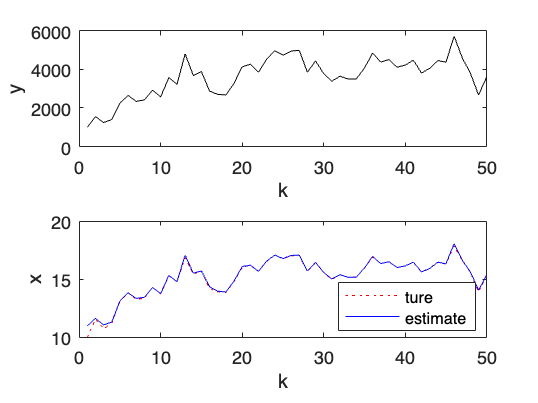

figure(1), clf
% y
subplot(2, 1, 1);
    plot(1:N, y, 'k');
    xlabel('k'), ylabel('y');
% x
subplot(2, 1, 2);
    plot(1:N, x, 'r:', 1:N, xhat, 'b-');%, 1:N, y, 'k');
    xlabel('k'), ylabel('x');
    legend('ture', 'estimate', 'Location', 'SouthEast');

### EKFのfunction文

function [xhat_new, P_new, G] = ekf(f, h, A, B, C, Q, R, y, xhat, P)

EKF拡張カルマンフィルタの更新式

[xhat_new, P_new, G] = ekf(f, h, A, B, C, Q, R, y, xhat, P)

線形カルマンフィルタの推定値更新を行う

引数：

    f, h, B: 対象システム

        x(k+1) = f(x(k)) + Bv(k)

        y(k) = h(x(k)) + w(k)

        を記述する関数への関数ハンドル f, h および行列 B

    注意：対象システムが既知の制御入力 u を持つ関数 fu(x(k), u(k))

    で記述される場合

    f = @(x) fu(x, u(k))

    を与えれば良い．

A, C: f, hのヤコビアンを’計算する関数への関数ハンドル

Q, R: 雑音v, w の共分散行列．v, wは正規性白色雑音で

    E[v(k)] = E[w(k)] = 0

    E[v(k)' v(k)] = Q, E[w(k)' w(k) = R

    であることを想定

y: 状態更新後時点での観測出力 y(k)

xhat, P: 更新前の状態推定値 xhat(k-1) (行ベクトル) ,  誤差共分散行列 P(k-1)  

戻り値：

    xhat_new: 更新後の状態推定値 xhat(k)

    P_new: 更新後の誤差共分散行列 P(k)

    G: カルマンゲイン G(k)

参考：

    線形カルマンフィルタ: KF

    Unscented カルマンフィルタ： UKF

% 列ベクトルに整形
xhat = xhat(:);
y = y(:);
% 事前推定値
xhatm = f(xhat); % 状態
Pm = A(xhat)*P*A(xhat)' + B*Q*B'; % 誤差共分散
% カルマンゲイン
G = Pm*C(xhatm)/(C(xhatm)'*Pm*C(xhatm)+R);
% 事後推定値
xhat_new = xhatm + G*(y-h(xhatm)); % 状態
P_new = (eye(size(A(xhat))) - G*C(xhatm)') * Pm; % 誤差共分散
end